# Propagation de faisceau

Le code se décompose ainsi : 

-1) On pose les variables

-2) On calcule et enregistre tous les plans de calculs entre U_incident et U_final pour une défocalisation donnée  (très rapide)

-3) On fait une boucle de calcul à partir du moment ou l'on multiplie par la fonction de transfert de l'espace libre pour enregistrer différent plans U_finaux en les agrégeant pour faire une matrice 3D afin d'avoir le faisceau en entier. Dans cette boucle on enregistre aussi le Spot_RMS et l'énergie encerclé pour chaque plan. (temps de caculs modéré)

-4) On affiche les plans successifs X,Y calculés en partie 2)

-5) On affiche les plans de coupes 3D de l'intensité du faisceau (gros temps de calcul) /!\ seulement lancer cette partie si on a lancé la partie (3)

-6)On affiche les plans de coupes 2D Y,Z ,l'energie encerclé et le Spot_RMS en fonction de la défocalisation, l'énergie encerclé au meilleur foyer RMS en fonction du rayon

Tous les affichages sont segmentés, Les parties 1 2 ese lancent ensembles le reste est lancé de manière séparé

## `PARTIE I `

#### Variables physiques et numériques / Données

N = 2.^8;% Nombre d'échantillonnage, de 2.^8 pour lambda/4 à 2.^10 pour lambda/1
% /!\ ne pas aller au delà de 2.^9 pour l'affichage 3D
% /!\ ne pas aller au delà de 2.^10 dans tous les cas 
S = 0.05;% demi-côté du support (carré) de la pupille (circulaire) [en mètre] 
r0 = 0.020;% rayon pupille [en mètre]
f = 0.15; % focale de la lentille [en metre]
lambda = 600*10^-9; % longueur d'onde de l'onde incidente [en mètre]
l = lambda ; %abrégé

dx = 2*S/N; % pas d'échantillonnage spatial, abcisse [en mètre]
df = 1/(dx*N); % pas d'échantillonnage fréquentiel [en mètre^-1]
x = dx * (-N/2:N/2-1); % tableau (1,N) des pas d'échantillonnage spatiaux, centré en 0, de pas dx
y = x; % pas d'échantillonnage spatial, ordonnée [en mètre]
[X,Y]=meshgrid(x,y); % matrice de taille (N,N).


eps0 = (10^-4)/5;  % pas d'échantillonnage de la défocalisation [en metre]
eps = eps0 * (-100:100) ; %liste de défocalisation


#### `Choix Amplitude incidente + aberrations`

 % onde incidente, onde plane d'amplitude uniforme, sans incidence

wo = 1*10^-3;
w = lambda * f ./ (wo * pi) % waist attendu à l'arrivé pour l'onde gaussienne.

w = 2.8648e-05

Uinc = gaussian(wo,x,y); % onde incidente gaussienne

%Uinc = 1; % onde plane pour étudier les aberrations

Delta_aberr = aberration_front(x,y,r0,0,0,0,0,0); %coeffs sigma de Zernike (sph, coma, ast0 , ast45, defocus,trefoil) en metre (de l'ordre de lambda/10)

## `PARTIE II`

#### `Plan pupille`

[disq,x,y]=PorteDisqueR1(N,S,r0); % génération de la pupille

U0 = disq.*Uinc .* exp(2*1i*pi*Delta_aberr/lambda); % onde juste après la lentille avec ajout d'aberrations

#### `Plan focal`

M2=ifftshift(U0); % shiftage dans le plan objet pour anéantir la varicelle, éviter le saut de phase. 
U_focal=fftshift(fft2(M2)); % amplitude de l'onde incidente au foyer paraxial, espace réel. 

dx1 =df *(lambda*f); % pas d'échantillonnage spatial du plan focal, abcisse
dy1  =dx1; % pas d'échantillonnage spatial du plan focal, ordonnée
x1 = dx1 * (-N/2:N/2-1); % tableau des pas d'échantillonnage spatiaux du plan focal centré en 0, abscisse
y1 = x1; % tableau des pas d'échantillonnage spatiaux du plan focal centré en 0, ordonnée 
[X1,Y1] = meshgrid(x1,y1);
S1 = x1(N/2-1); %demi coté du plan étudié en metre


U_focal_tild = U0 ;% Raccourci pour faire moins de calcul. numériquement on a bien
                   % U_focal_tild = U0. car double TF.

df1 = 1/(dx1*N); % pas d'échantillonnage fréquentiel dans l'espace de Fourrier 
vx1 =  df1 * (-N/2:N/2-1); % tableau des pas d'échantillonnage fréquentiels dans l'espace de Fourrier centrés en 0, abcisse
vy1 = vx1; % tableau des pas d'échantillonnage fréquentiels dans l'espace de Fourrier centrés en 0, ordonnée
[Vx1,Vy1] = meshgrid(vx1,vy1);

#### `Passage en fréquentiel`

% Fonction de déplacement. Permettra de déplacer U_focal_tild d'une quantité "eps0" (troisième argument de Hd) autour du foyer paraxial dans l'espace de Fourrier. 
Hd = fonction_transfert_espacelibre(Vx1,Vy1,40*10^-6,lambda); % Faire attention à bien mettre les variables [Vx,Vy] (= meshgrid(vx,vy)) dans les deux premiers arguments  Hd /!\ 

% Amplitude de l'onde dans l'espace de Fourrier, déplacée de "eps0" autour du foyer paraxial.
U_defocal_tild = Hd .* U_focal_tild;

#### `Plan défocalisation`

M2=ifftshift(U_defocal_tild); % shiftage dans le plan objet pour anéantir la varicelle 
U_defocal1=fftshift(ifft2(M2)); %TF^-1 de U_defocal_tild, retour dans l'espace réel.  

## `PARTIE III`

#### `Boucles de calculs pour une succession de plans de défocalisation`

%On va réaliser plusieurs coupes du faisceau afin d'avoir une matrice 3D de
%celui-ci afin de pouvoir ensuite la couper (slice) pour avoir une
%affichage 3d du faisceau

%initialisation du plan de coupe Y,Z et du volume faisceau
Plan_coupe_vertical = zeros(N,length(eps)); % rappel : eps = eps0 * (-100:100)  
Rayon_Tot = zeros(N,N); %on incrémentera chaque plan calculé pour faire au 
% final un volume d'épaisseur 201
%-------------------------------------------------

%initialisation des critères d'optimisations selon l'axe Z (epsilon)
rE = abs(S1/6);%definition du cercle d'énergie. Ici, diametre = 1/6 du plan X,Y d'étude
E_encerclee = [] ;
RMS_spot = [] ;
%--------------------------------------------------

for i = 1:length(eps) % Remplissage de la matrice Plan_coupe_vertical et de la matrice 3D Rayon_Tot                                                                                                     
    Hd = fonction_transfert_espacelibre(Vx1,Vy1,eps(i),lambda); 

    U_defocal_tild = Hd .* U_focal_tild;

    M2=ifftshift(U_defocal_tild); 
    U_defocal=fftshift(ifft2(M2)); 
    
    I_defocal =  abs(U_defocal).^2;


    Rayon_Tot(:,:,i) = U_defocal;   % c'est une matrice en 3D regroupant en chaque point l'amplitude du faisceau incident.
    [disq1,~,~]=PorteDisqueR1(N,S1,rE) ;%Matrice masque disque
    

    E_encerclee(i) = sum(I_defocal.*disq1,"all")/sum(I_defocal,"all");
   
    RMS_spot(i) = (sum(((X1.^2+Y1.^2).*I_defocal),"all")/sum(I_defocal,"all")).^0.5;

    for j = 1:N 
    
    Plan_coupe_vertical(j,i) =U_defocal(j,N/2+1); %collage pour réaliser une vue en coupe du faisceau le long de l'axe 
    
    end 
end

%-----posbesrms et E encerle----
[Best_RMS,ind_Best_RMS] = min(RMS_spot);
Best_eps_RMS = eps(ind_Best_RMS);
disp(['Le meilleur foyer RMS est situé en f + ', num2str(Best_eps_RMS*1000) ' mm et vaut : ', num2str(Best_RMS*10^6) ' micro metre'])

Le meilleur foyer RMS est situé en f + 0 mm et vaut : 20.2571 micro metre



[Best_Eenc,ind_Best_Eenc] = max(E_encerclee);
Best_eps_Eenc = eps(ind_Best_Eenc) ;
disp(['Le meilleur foyer E_{encerclé} pour un rayon de ',num2str(rE*10^6), 'micro metre est situé en f + ', num2str(Best_eps_Eenc*1000) ' mm et vaut : ',num2str(Best_Eenc)])

Le meilleur foyer E_{encerclé} pour un rayon de 0.3micro metre est situé en f + 0 mm et vaut : 0.59358


%----------------------------------


%E_encerclé au meilleur foyer RMS en fonction du rayon considéré
I_defocal_meilleur_foyer = abs(Rayon_Tot(:,:,ind_Best_RMS)).^2;

E_encerclee_meilleur_foyer = [];
r_E = linspace(0,abs(S1/4),N/2+1);

for i = 1:N/2+1
    [disq2,~,~]=PorteDisqueR1(N,S1,r_E(i));
    E_encerclee_meilleur_foyer(i) = sum(I_defocal_meilleur_foyer .*disq2,"all")/sum(I_defocal_meilleur_foyer ,"all");
end
%----------------------------------------------------------------



## `PARTIE IV`

#### `Affichages 2D plans X,Y pour un Epsilon choisi`

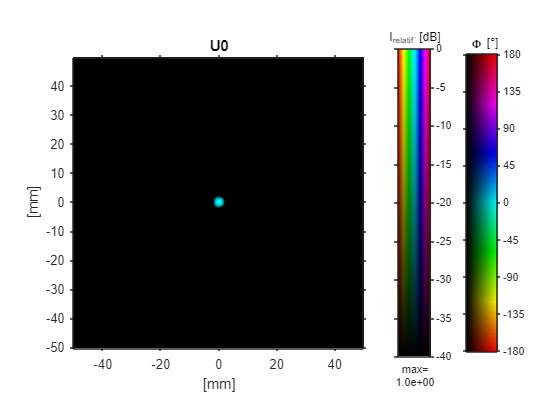

figure
VisuIdBPh(x*10^3,y*10^3,U0,-40)
xlabel("[mm]" )
ylabel("[mm]")
title("U0")

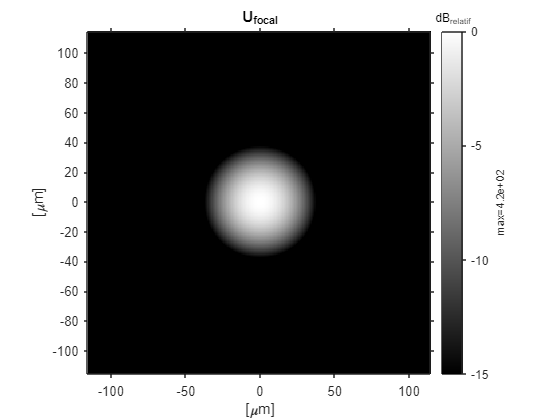

figure % visualisation de U_focal 
VisuIdB(x1*10^6,y1*10^6,U_focal,-15)
title("U_{focal}")
xlabel("[\mum]" )
ylabel("[\mum]")

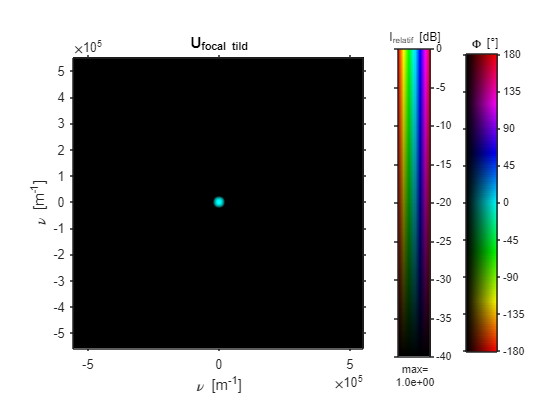

figure % visualisation de U_focal_tild
VisuIdBPh(vx1,vy1,U_focal_tild,-40)
xlabel("\nu [m^{-1}]" )
ylabel("\nu [m^{-1}]")
title("U_{focal tild}")

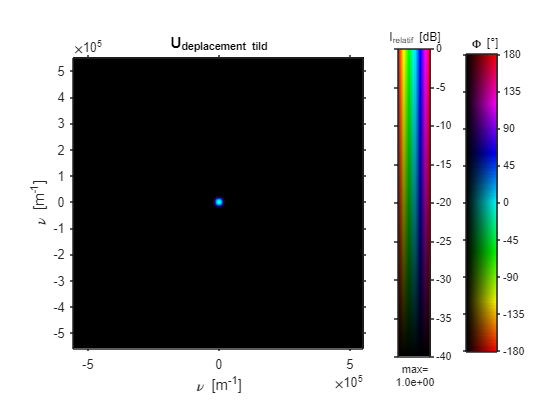

figure % visualisation de U_defocal_tild
VisuIdBPh(vx1,vy1,U_defocal_tild,-40)
xlabel("\nu [m^{-1}]" )
ylabel("\nu [m^{-1}]")
title("U_{deplacement tild}")

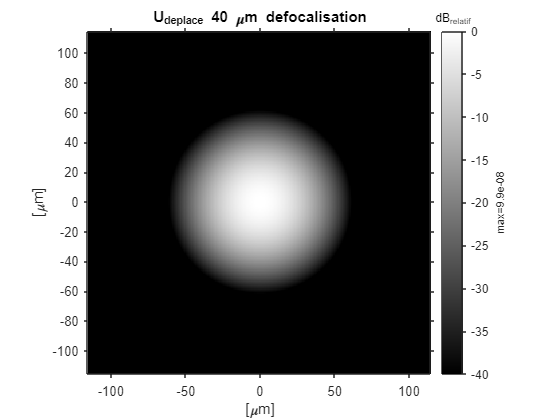

figure %Visualisation de U_defocal
VisuIdB(x1*10^6,y1*10^6,U_defocal1,-40)
xlabel("[\mum]" )
ylabel("[\mum]")
title("U_{deplace} " + num2str(40) + " \mum defocalisation" )

## `PARTIE V`

#### `Affichage 3D`

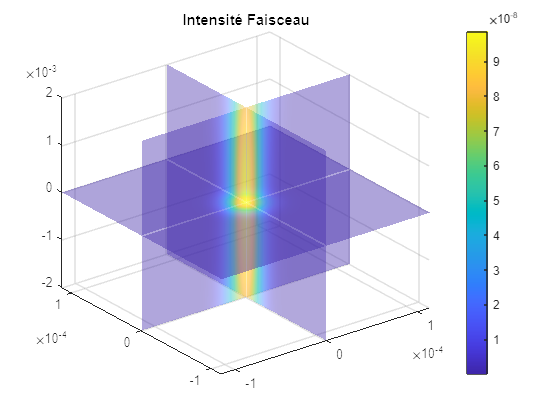

% %affichage 3D en phase 
% figure;
% xslice = 0;
% yslice = 0;             % Plans de coupe (z étant l'axe optique)
% zslice = 0;   %z  = 0 correspond au point focal, on se place ici au meilleur foyer
% slice(x1,y1,eps,angle(Rayon_Tot),xslice,yslice,zslice); %explication de slice en annexe du code
% view(3);
% axis on;
% grid on;
% colormap(hsv(64)); %colormap de tel sorte à ce que la couleur pour la valeur la plus basse (-pi) soit la meme que celle pour la valeur la plus haute (+pi)
% colorbar;
% shading interp;
% title("Phase Faisceau")

%affichage 3D en intensité (champ electrique) rayon tot au carré
figure; 
xslice = 0;
yslice = 0;           % Plans de coupe (z étant l'axe optique)
zslice = 0;   %z  = 0 correspond au point focal
h = slice(x1, y1, eps, abs(Rayon_Tot).^2, xslice, yslice, zslice);
view(3);
axis on;
grid on;
%moyen d'ajouter de la transparence à l'affichage 3d 
nColors = 64;
colormapWithAlpha = jet(nColors);
alphaValues = linspace(0.40, 1, nColors);
alpha('scaled');
for i = 1:numel(h)
    alpha(h(i), alphaValues(i));
end

shading interp;

colorbar;

set(gcf, 'Color', 'w');
title("Intensité Faisceau")

## `PARTIE VI`

#### `Affichage 2D Plan Y,Z`

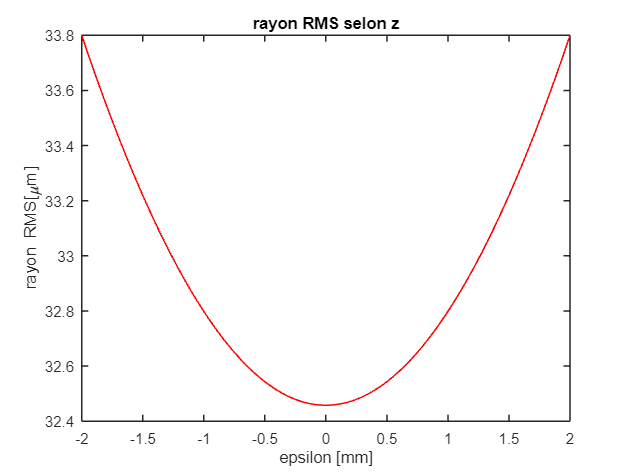

figure
plot(eps*1000,RMS_spot*10^6);
title("rayon RMS selon z")
xlabel("epsilon [mm]" )
ylabel("rayon RMS[\mum]")

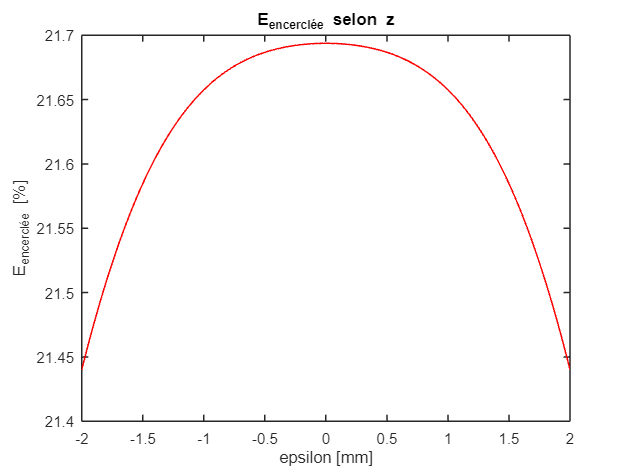

figure
plot(eps*1000,E_encerclee*100);
title("E_{encerclée} selon z")
xlabel("epsilon [mm]" )
ylabel("E_{encerclée} [%]")

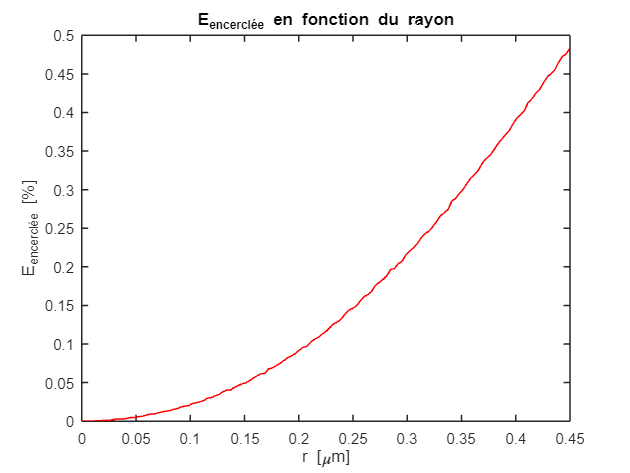

figure
plot(r_E*10^6,E_encerclee_meilleur_foyer)
title("E_{encerclée} en fonction du rayon")
xlabel("r [\mum]" )
ylabel("E_{encerclée} [%]")

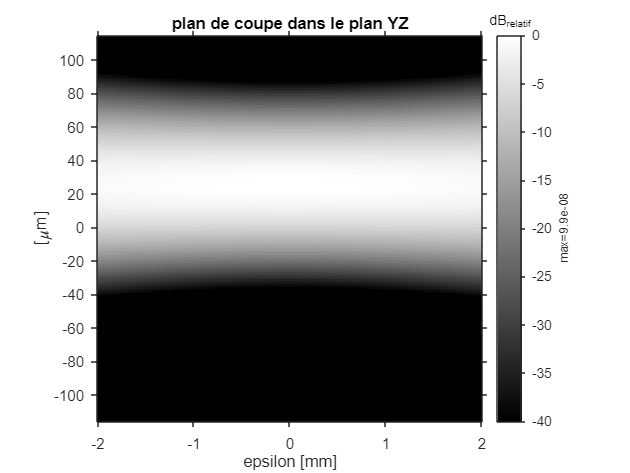


figure
VisuIdB(eps*1000,y1*10^6,Plan_coupe_vertical,-40)
title("plan de coupe dans le plan YZ")
axis("square")
xlabel("epsilon [mm]" )
ylabel("[\mum]")

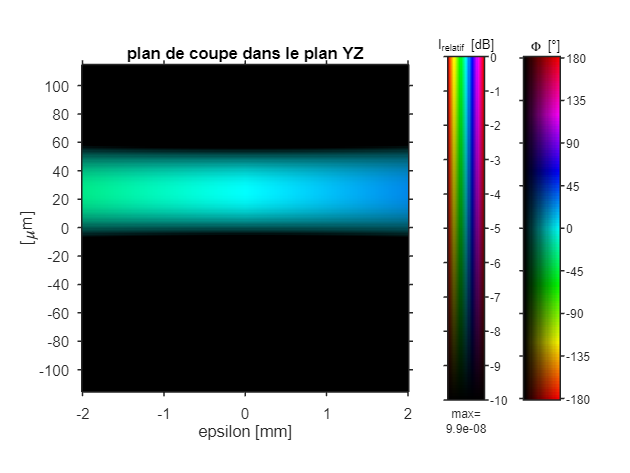

figure

VisuIdBPh(eps*1000,y1*10^6,Plan_coupe_vertical,-10)
title("plan de coupe dans le plan YZ")
axis("square")
xlabel("epsilon [mm]" )
ylabel("[\mum]")

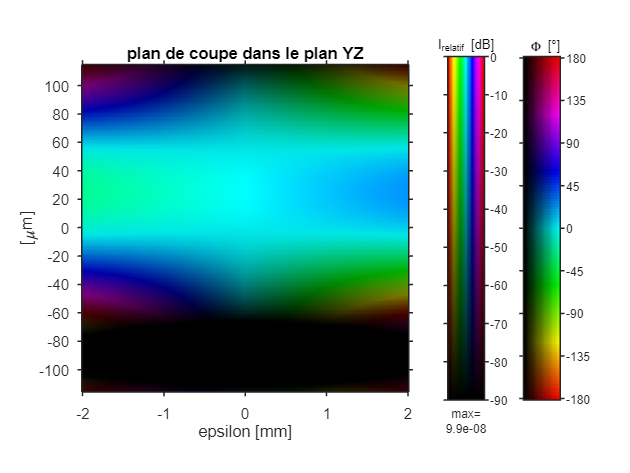


figure
VisuIdBPh(eps*1000,y1*10^6,Plan_coupe_vertical,-90)
title("plan de coupe dans le plan YZ")
axis("square")
xlabel("epsilon [mm]" )
ylabel("[\mum]")

#### `Fonctions`

function U = gaussian(wo,x,y)
        [X,Y]=meshgrid(x,y);
        X2 = X.^2;
        Y2 = Y.^2;
        U = exp(-(X2+Y2)./wo^2);
end

function Delta_aberr = aberration_front(x,y,r0,sph,coma,asti0,asti45,defocus)
      N = length(x);
    [X,Y]=meshgrid(x,y);
    M1=double(X.^2+Y.^2<=r0.^2);
    r  = (X.^2+Y.^2).^0.5;
    r = r .*M1;
    u = r/r0;

    phi = atan2(X,Y);
    phi(N/2+1,N/2+1) = 0;
    Delta_aberr = sph*5^0.5*(6*(r/r0).^4-(6*(r/r0).^2)+1) + coma*8^0.5*(3*u.^3-2*u).*cos(phi) + asti0*(6^0.5*u.^2).*cos(2*phi) + (asti45*6^0.5*u.^2).*sin(2*phi) + defocus*3^0.5*(r/r0).^2 ;
end

function [M,x,y]=PorteDisqueR1(N,S,P) % FONCTION DU TD
% PorteDisqueR1 - calcule l'éch. fonc. porte/disqR1 dans [-S,+S[×[-S,+S[
% USAGE: [M,x,y]=PorteDisqueR1(N,S)
% N: scalaire entier positif PAIR, la taille de l'échantillonnage à créer
% S: scalaire réel positif > 1, la taille du carré dans lequel est représentée
% la fonction porte sur un disque
% M: matrice réelle de taille N×N contenant l'échantillonnage de la fonction
% porte, disque centré de manière à ce que
% ifftshift(M) place le centre du disque en (1,1).
% x,y: vecteurs réels décrivant l'échantillonnage des x et y.
% AffImGris(x,y,M) peut représenter le résultat.
if N<2 || mod(N,2)~=0
 error('N n''est dx un nombre entier PAIR strictement positif')
end
dx=2*S/N;
x=dx*(-N/2:N/2-1);
% on aurait aussi pu écrire «x=linspace(-S,S,N+1);x(N+1)=[];»
y=x;
[X,Y]=meshgrid(x,y);
M=double(X.^2+Y.^2<=P.^2);
end

function Hd = fonction_transfert_espacelibre(Vx,Vy,d,lambda);
Hd = exp(1i*pi*lambda*d*(Vx.^2+Vy.^2));
end

#### `Annexes`

`Slice est une fonction qui prend en input un array en 3 dimension et qui l'affiche en prenant plusieurs plans de coupe, on peut bien sûr dimensionner les axes et afficher de différentes manières.`